clear

addpath("matlab_functions\")

#### Compare coil electric field

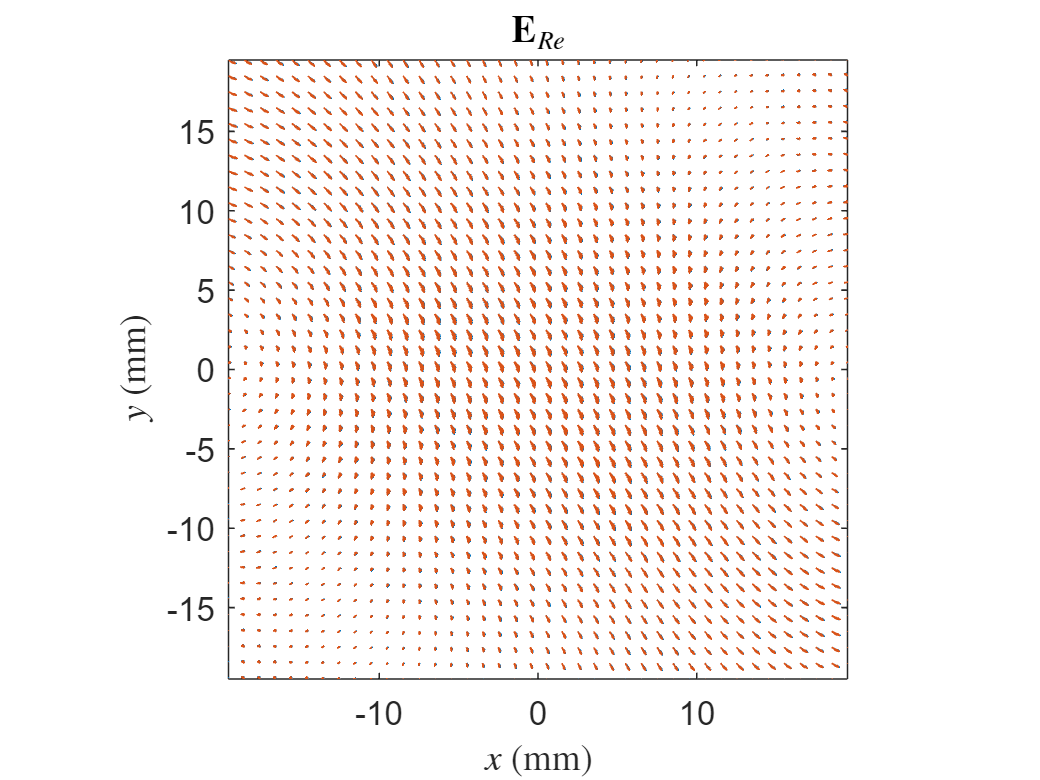

error: 7.14702%

[Plate, Coil, ~, Model] = myModel;
freq = 100; % (Hz)

x = Plate.elems_center(1,:);
y = Plate.elems_center(2,:);
z = Plate.elems_center(3,:);

[Ex,Ey] = CoilElectricField(Coil, Plate, x,y,z, 2*pi*freq);

ComsolModel('SolveCoil', Model, Coil, freq, 5);
E = ComsolModel('InterpField', Model, 'E', [x;y;z]);

scale = 1 / max(vecnorm([Ex;Ey]));

CompareField(x,y, real(Ex), real(Ey), real(E(1,:)), real(E(2,:)), scale, '$\textbf{E}_{Re}$')

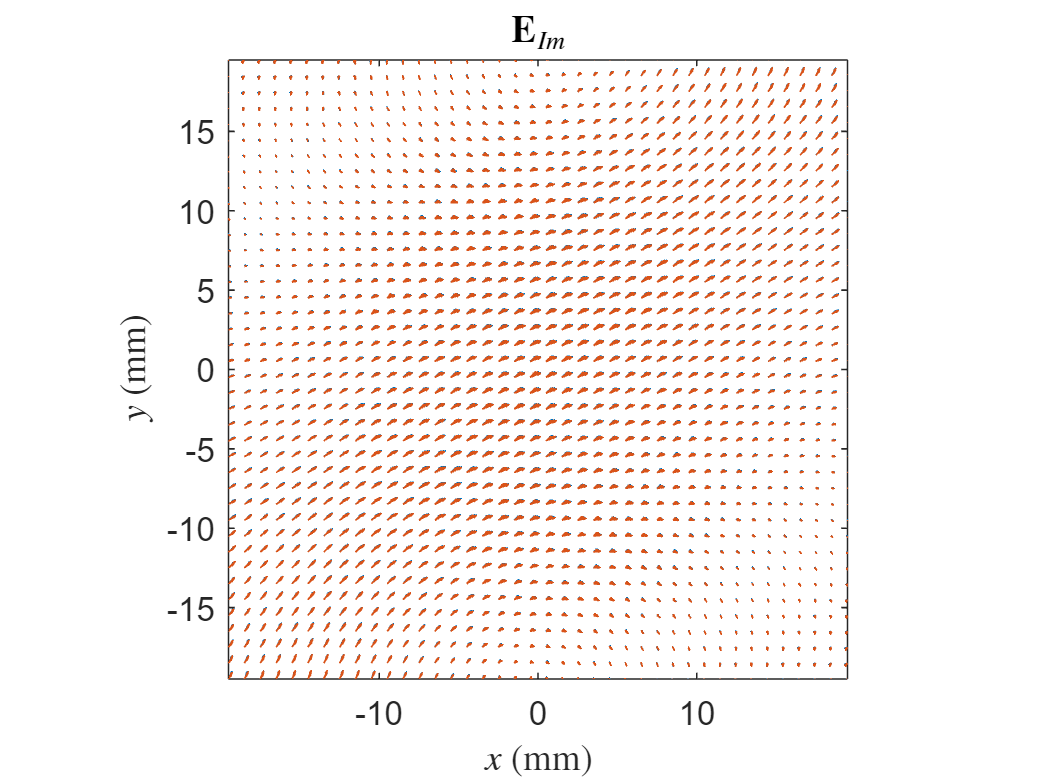

error: 7.16284%

CompareField(x,y, imag(Ex), imag(Ey), imag(E(1,:)), imag(E(2,:)), scale, '$\textbf{E}_{Im}$')

#### Compare sensor electric field

[Plate, ~, Sensor, Model] = myModel;
Sensor.positions = [0 0 4e-3]';
Sensor.axes = [0 1 0]';
Sensor.compute_index = 1;

freq = 100; % (Hz)

x = Plate.elems_center(1,:);
y = Plate.elems_center(2,:);
z = Plate.elems_center(3,:);

[Ex,Ey] = SensorElectricField(Sensor, Plate, x,y,z, 2*pi*freq);

ComsolModel('SolveSensor', Model, Sensor, freq, 5);
E = ComsolModel('InterpField', Model, 'E', [x;y;z]);

[~,i] = min(vecnorm(Plate.elems_center));
c = norm([Ex(i) Ey(i)]) / norm(E(:,i));
E = E * c;
disp(c)

    8.7740



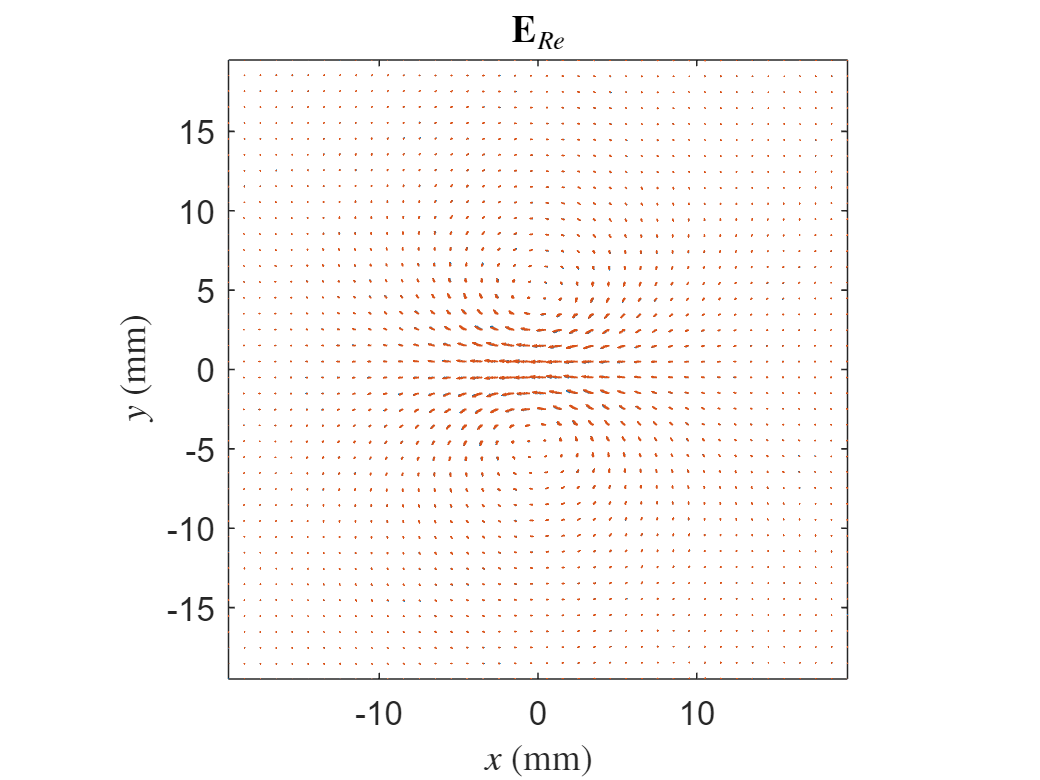

error: 7.28668%


scale = 1 / max(vecnorm([Ex;Ey]));

CompareField(x,y, real(Ex), real(Ey), real(E(1,:)), real(E(2,:)), scale, '$\textbf{E}_{Re}$')

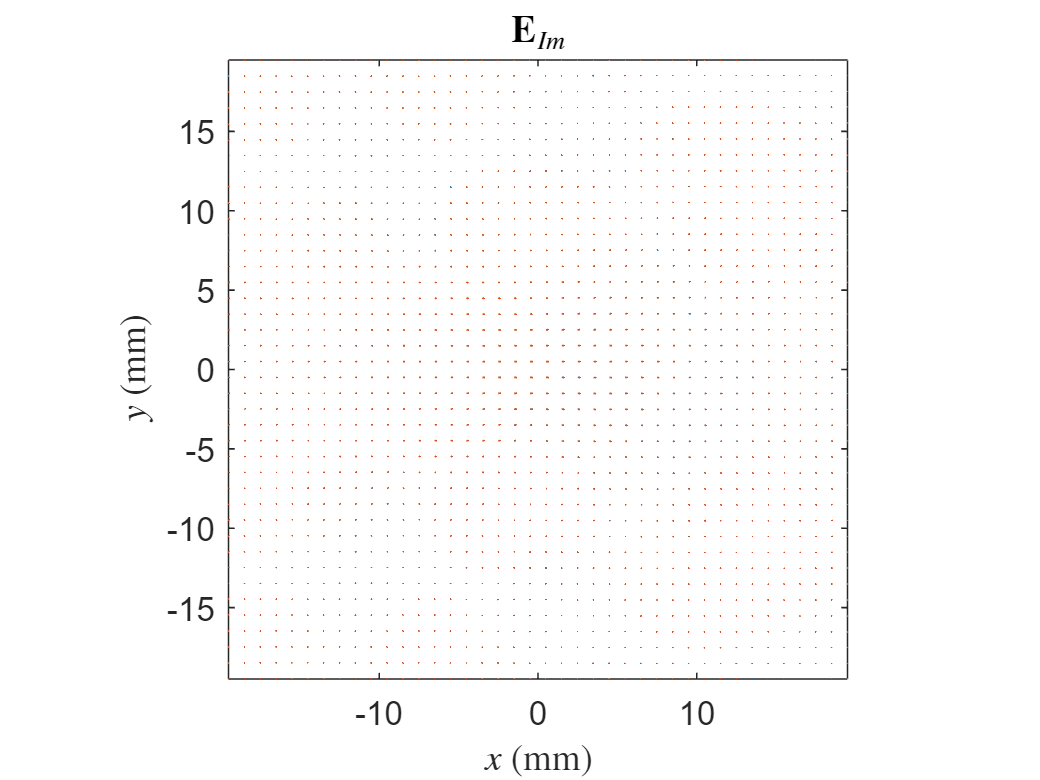

error: 5.75862%

CompareField(x,y, imag(Ex), imag(Ey), imag(E(1,:)), imag(E(2,:)), scale, '$\textbf{E}_{Im}$')

function [Ex,Ey] = CoilElectricField(Coil, Plate, x,y,z, omega)

if Coil.fillet ~= Coil.width / 2
    error('Only support cylindrical coil')
end
zc = unique(Coil.positions(3,:));
if numel(zc) ~= 1
    error('Coils must be at the same z position')
end
r2 = Coil.width / 2;
r1 = r2 - Coil.thickness;
z2 = zc + Coil.height / 2;
z1 = zc - Coil.height / 2;
N = Coil.N_turns;

coil = struct('r1',r1,'r2',r2,'z1',z1,'z2',z2,'N',N);
layers{1}.sigma     = Plate.conductivity;
layers{1}.mur       = Plate.relative_permeability;
layers{1}.thickness = Plate.height;
layers{2} = struct('sigma',0, 'mur',1, 'thickness',Inf);
coilAbovePlate = CoilAbovePlate2D(coil, layers);

Ex = 0;
Ey = 0;
for k = 1:size(Coil.positions,2)
    [theta,r] = cart2pol(x-Coil.positions(1,k), y-Coil.positions(2,k));
    E_theta = coilAbovePlate.E_theta(r,z,omega) * Coil.current(k);
    Ex = Ex + E_theta .* -sin(theta);
    Ey = Ey + E_theta .*  cos(theta);
end

end

function [Ex,Ey] = SensorElectricField(Sensor, Plate, x,y,z, omega)

sigma = Plate.conductivity;
mur   = Plate.relative_permeability;
d     = Plate.height;

k = Sensor.compute_index;
sensorAbovePlate = SensorAbovePlate(Sensor.positions(3,k), Sensor.axes(:,k), sigma,mur,d);

[Ex,Ey] = sensorAbovePlate.E(x-Sensor.positions(1,k), y-Sensor.positions(2,k), z, omega);

end

function CompareField(x,y, E1x,E1y, E2x,E2y, scale, titlestr)

figure
hold on
quiver(x*1e3, y*1e3, E1x*scale, E1y*scale, 'off')
quiver(x*1e3, y*1e3, E2x*scale, E2y*scale, 'off')
xlim([min(x) max(x)] * 1e3)
ylim([min(y) max(y)] * 1e3)
axis square
box on
title(titlestr, 'Interpreter','latex')
xlabel('$x$ (mm)', 'Interpreter','latex')
ylabel('$y$ (mm)', 'Interpreter','latex')

error = sqrt((E1x-E2x).^2 + (E1y-E2y).^2);
base = sqrt(E1x.^2 + E1y.^2);

fprintf("error: %g%%", mean(error) / mean(base) * 100)

end